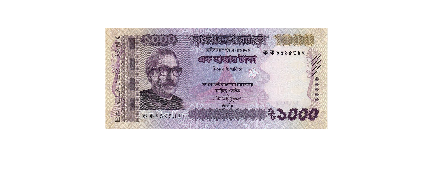

filename = '1000.jpg';
I = imread(filename);
resized = imresize(I, [400, 880]);
imshow(resized);

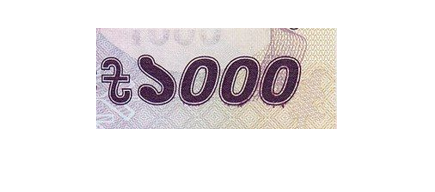

roi = imcrop(resized, [640, 290, 240, 100]);
imshow(roi)

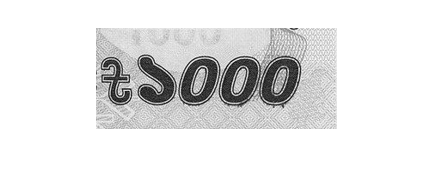

gray = rgb2gray(roi);
imshow(gray)

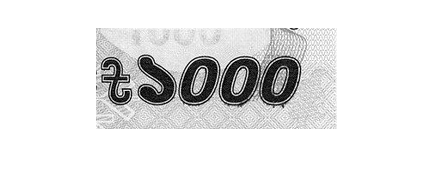

enhanced = imadjust(gray);
imshow(enhanced);

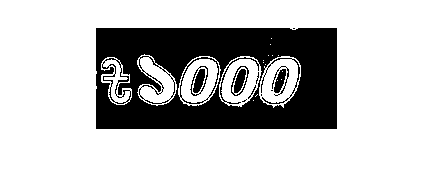

threshold = graythresh(enhanced);
bin = ~imbinarize(enhanced, threshold);
imshow(bin)

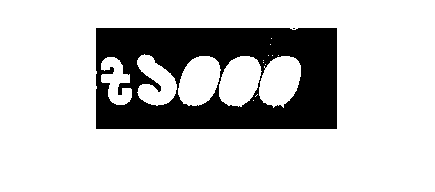

filled = imfill(bin, 'holes');
imshow(filled)

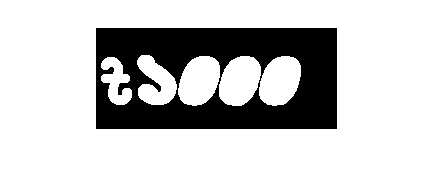

opened = bwareaopen(filled, 900);
se = strel('disk', 5);
opened = imopen(opened, se);
imshow(opened);

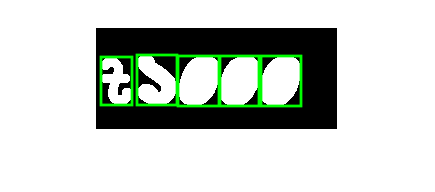

imshow(opened);
hold on;
[L, N] = bwlabel(opened);
boxes = regionprops(L, 'BoundingBox');
for i = 1 : N
    rectangle('Position',boxes(i).BoundingBox,...
        'EdgeColor','g','LineWidth',2)
end
hold off;

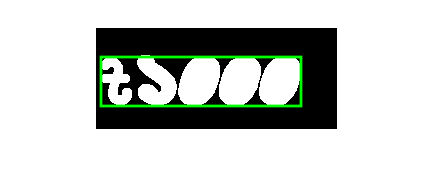

start_x = boxes(1).BoundingBox(1);
start_y = boxes(1).BoundingBox(2);
end_x = boxes(end).BoundingBox(1) + ...
    boxes(end).BoundingBox(3);
end_y = boxes(end).BoundingBox(2) + ...
    boxes(end).BoundingBox(4);

width = end_x - start_x;
height = end_y - start_y;

imshow(opened);
hold on;
rectangle('Position', [start_x, start_y, width, height],...
        'EdgeColor','g','LineWidth',2);
hold off;

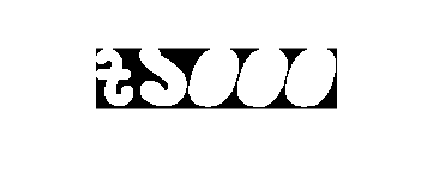

roi = imcrop(opened, [start_x, start_y,...
    width, height]);
imshow(roi)

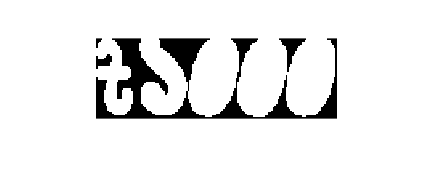

roi_res = imresize(roi, [50, 150]);
imshow(roi_res)

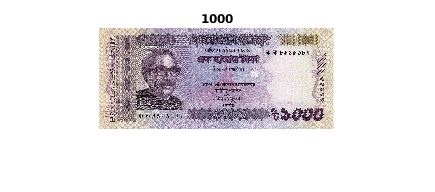

similarity = 0.2258

similarity = 0.1877

similarity = 0.1519

similarity = 0.2786

similarity = 0.2660

similarity = 0.3373

similarity = 0.9983

imshow(I)
notes = ["5", "10", "20", "50", ...
    "100", "500", "1000"];

for i = 1 : length(notes)
    base_image = imread(strcat('base/', notes(i), '.jpg'));
    similarity = corr2(roi_res, base_image)
    if(similarity > 0.9)
        title(notes(i))
    end
end